# Calcualtion of Inter Hamming Distance for all devices without AuNPs

For this test, we compare all combinations of the response of the same device type and compute the al HD metrics for each design. We then generate plots of  Hamming Distance combining all resulting HDs.

## Read data

First extract the data from the H5 file. 

clear('files', 'results_dev1', 'results_dev2', 'results_dev3');
folder = 'G:\My Drive\PRL Group\04 Projects\2 Juan\1 OPUF ANT2 CHIP02\with AuNP\';
files{1} = 'AllDevices_Au0_Chips02_01_TE_user01_1504.smp';
files{2} = 'AllDevices_Au0_Chips02_01_TM_user01_1504.smp';

idx = 1;
for file = files
    filename = strcat(folder,file{1});
    struct = h52struct(filename);
    data{idx} = struct.project.measurements; 
    idx = idx+1;
end

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We compare only the drop ports in the design 3 type of devices.
dev_ind   = 13:24;    % Index opf the oimetrest devices ()  
dev_port = ones(1,length(dev_ind)); dev_port(9:12) = 2;

ind_file = 1; clear dataset;
for file = files
    meas = data{ind_file} ;
    response=[];
    for i = 1:length(dev_ind)
        idx = findinproject(dev_ind(i),dev_port(i),meas);
        extract_meas = meas(idx); 
        if (iscell(extract_meas)), extract_meas = extract_meas{1};end
        m = extract_meas.spectra;
        response(:,i) = m(:,2);
        lambda = m(:,1);
    end
    dataset{ind_file} = response;
    ind_file = ind_file+1;
end

We now compute  the HD metrics for each file, the shifted datasets are computed inside of the function MultiHD

L=0.15; clear('results_dev1','results_dev2','results_dev3')
for file_ind = 1:2
    results_dev1{file_ind} = multi_HD(lambda, dataset{file_ind}(:,1:4 ), L);
    results_dev2{file_ind} = multi_HD(lambda, dataset{file_ind}(:,5:8 ), L);
    results_dev3{file_ind} = multi_HD(lambda, dataset{file_ind}(:,9:12), L);
end

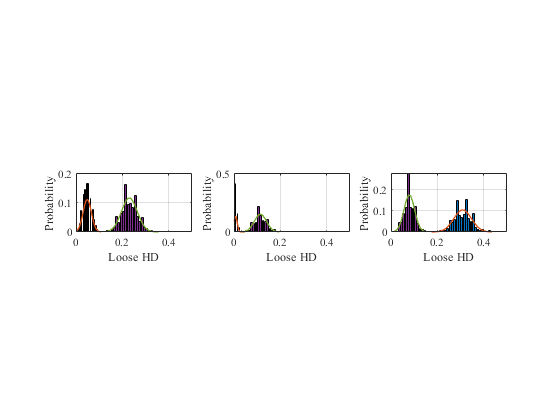

%Plot for TE response
 resultsAu0_dev1 = results_dev1;
 resultsAu0_dev2 = results_dev2;
 resultsAu0_dev3 = results_dev3;

    h = figure(); clf, hold off; haxis = [0,0.5];
    device = 4; metric = 3; %Metric: Loose HD
    subplot(1,3,1), 
        [xd,pd] = plotHD(resultsAu0_dev1{1}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
        hold on;
        [xd,pd] = plotHD(resultsAu0_dev1{2}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
    
    subplot(1,3,2), 
        [xd,pd] = plotHD(resultsAu0_dev2{1}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
        hold on;
        [xd,pd] = plotHD(resultsAu0_dev2{2}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on; 
    subplot(1,3,3),
        [xd,pd] = plotHD(resultsAu0_dev3{1}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;
        hold on;
        [xd,pd] = plotHD(resultsAu0_dev3{2}.HDData_s{metric}(:,device),'Loose HD',haxis); grid on;


   % exportgraphics(gcf,'InterHD_Au0.png','Resolution',1200,'BackgroundColor','#FFFFFF')
    
    %% TE distance metrics
    avg_TE(1,:) = mean(results_dev1{1}.mean{1});
    avg_TE(2,:) = mean(results_dev2{1}.mean{1});
    avg_TE(3,:) = mean(results_dev3{1}.mean{1}) %

avg_TE =     0.9740  245.2140    0.0611    0.1448    0.9761  226.2678    0.0518    0.1366
    0.9479  237.8116    0.0708    0.0762    0.9262  133.8531    0.0214    0.0477
    0.9922  548.7192    0.4184    0.3955    0.9870  428.3212    0.3027    0.3434


   
    sigma_TE(1,:) = mean(results_dev1{1}.mean{2});
    sigma_TE(2,:) = mean(results_dev2{1}.mean{2});
    sigma_TE(3,:) = mean(results_dev3{1}.mean{2})

sigma_TE =     0.0122   25.6923    0.0183    0.0379    0.0117   23.1516    0.0172    0.0372
    0.0180   33.5076    0.0206    0.0277    0.0208   26.8742    0.0111    0.0220
    0.0072   32.5861    0.0404    0.0532    0.0090   26.3315    0.0374    0.0538


    
    for j = 2:4 
        for i = 1:3
            fprintf('%2.3f\x00B1 %2.3f (%2.3f\x00B1 %2.3f) \t', ...
                avg_TE(i,j),sigma_TE(i,j),avg_TE(i,j+4),sigma_TE(i,j+4));
        end
        fprintf('\n');
    end

245.214± 25.692 (226.268± 23.152) 	237.812± 33.508 (133.853± 26.874) 	548.719± 32.586 (428.321± 26.331) 	0.061± 0.018 (0.052± 0.017) 	0.071± 0.021 (0.021± 0.011) 	0.418± 0.040 (0.303± 0.037) 	0.145± 0.038 (0.137± 0.037) 	0.076± 0.028 (0.048± 0.022) 	0.396± 0.053 (0.343± 0.054) 	

    
    
    
     %% TE distance metrics
    avg_TM(1,:) = mean(results_dev1{2}.mean{1});
    avg_TM(2,:) = mean(results_dev2{2}.mean{1});
    avg_TM(3,:) = mean(results_dev3{2}.mean{1}) %

avg_TM =     0.9861  441.4291    0.2588    0.2657    0.9860  442.4841    0.2606    0.2666
    0.9833  388.4241    0.2209    0.2353    0.9829  369.7532    0.1879    0.2220
    0.9809  391.4556    0.2058    0.2166    0.9724  253.1098    0.0706    0.1332


   
    sigma_TM(1,:) = mean(results_dev1{2}.mean{2});
    sigma_TM(2,:) = mean(results_dev2{2}.mean{2});
    sigma_TM(3,:) = mean(results_dev3{2}.mean{2})

sigma_TM =     0.0095   39.4205    0.0355    0.0505    0.0097   39.5342    0.0352    0.0508
    0.0106   29.8302    0.0342    0.0469    0.0104   30.6325    0.0318    0.0471
    0.0109   35.2658    0.0304    0.0431    0.0132   32.5910    0.0208    0.0380


    
    for j = 2:4 
        for i = 1:3
            fprintf('%2.3f\x00B1 %2.3f (%2.3f\x00B1 %2.3f) \t', ...
                avg_TM(i,j),sigma_TE(i,j),avg_TM(i,j+4),sigma_TE(i,j+4));
        end
        fprintf('\n');
    end

441.429± 25.692 (442.484± 23.152) 	388.424± 33.508 (369.753± 26.874) 	391.456± 32.586 (253.110± 26.331) 	0.259± 0.018 (0.261± 0.017) 	0.221± 0.021 (0.188± 0.011) 	0.206± 0.040 (0.071± 0.037) 	0.266± 0.038 (0.267± 0.037) 	0.235± 0.028 (0.222± 0.022) 	0.217± 0.053 (0.133± 0.054) 	